# Válogatott modellek a matematikai biológiában

# 1. gyakorlat

## Leslie féle stabilizálódó korfa

A populációt $n$ db korcsoportra osztjuk:

n = 4;

Születési és túlélési ráták:

s = sym('s',[1,n-1]);
b = sym('b',[1,n-1]);
syms lambda

L_sym = [ [0 , b] ; [diag(s) , zeros(n-1,1)] ]

$$L\_sym = \left(\begin{array}{cccc} 0 & b_{1} & b_{2} & b_{3}\\ s_{1} & 0 & 0 & 0\\ 0 & s_{2} & 0 & 0\\ 0 & 0 & s_{3} & 0 \end{array}\right)$$

p = det(lambda*eye(n) - L_sym)

$$p = \lambda^{4}-b_{1}\,s_{1}\,\lambda^{2}-b_{2}\,s_{1}\,s_{2}\,\lambda -b_{3}\,s_{1}\,s_{2}\,s_{3}$$

R_sym = 1 - subs(p,lambda,1)

$$R\_sym = b_{1}\,s_{1}+b_{2}\,s_{1}\,s_{2}+b_{3}\,s_{1}\,s_{2}\,s_{3}$$

... ami lényegében a reprodukciós ráta.

L_fh = matlabFunction(L_sym,'Vars',{[b,s]});
R_fh = matlabFunction(R_sym,'Vars',{[b,s]});

bs_Idx = find(L_sym.');
RL_impl = @(L) R_fh(L(bs_Idx)')

RL_impl = function_handle with value:
    @(L)R_fh(L(bs_Idx)')

RL_fh = @(L) RL_impl(L');

#### Néhány lehetséges $L$ mátrix:

Általános Leslie mátrix

LL{1} = [
    0 1 1 1
    1 0 0 0
    0 1 0 0
    0 0 1 0 ];
RL_fh(LL{1})

ans = 3

L mx: irreducibilis, Pl: Csertölgy csak minden 2. évben terem

LL{2} = [
    0 1/2 0 1/2
    1  0  0  0 
    0  1  0  0
    0  0  1  0 ];
RL_fh(LL{2})

ans = 1

L mx: primitív, Pl: idõsebb egyedek szaporodnak csak 

LL{3} = [
    0   0   2   6
    1/2 0   0   0
    0   1/2 0   0
    0   0   1/3 0 ];
RL_fh(LL{3})

ans = 1

Sok születés, fiatal egyedek szaporábbak, gyengébb életkilátások: hagyományos társadalom 

LL{4} = [
    0   1  0.75 0.5
    0.5 0  0    0
    0   1  0    0
    0   0  0.5  0  ];
RL_fh(LL{4})

ans = 1

Sok születés, fiatal egyedek szaporábbak, jobb életkörülmények: népességrobbanás 

LL{5} = [
    0  1  0.75 0.5
    1  0  0    0
    0  1  0    0
    0  0  0.5  0 ]; 
RL_fh(LL{5})

ans = 2

Kevés születés, bár sokáig aktív egyedek: elöregedõ társadalom 

LL{6} = [
    0  0.25 0.25 0.25
    1  0    0    0
    0  1    0    0
    0  0    1    0  ];
RL_fh(LL{6})

ans = 0.7500

nem minden mátrix egyenlítõdik ki, pl. a következő mátrix a hatványozáskor ciklikusan magába visszatérő. Pl: cserebogarak 4 évesen szaporodnak 1szer, a populáció szinkronban 

LL{7} = [
    0 0 0 1
    1 0 0 0 
    0 1 0 0
    0 0 1 0 ]; %
RL_fh(LL{7})

ans = 1

#### Populációdinamika szimulációja

L = LL{7};
RL_fh(L)

ans = 1

% Gr = digraph(L');
% Pl_Gr = plot(Gr);
x0 = [1 0 0 0]';
% x0 = rand(4,1);

eigs = eig(L)

eigs =   -1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   1.0000 + 0.0000i


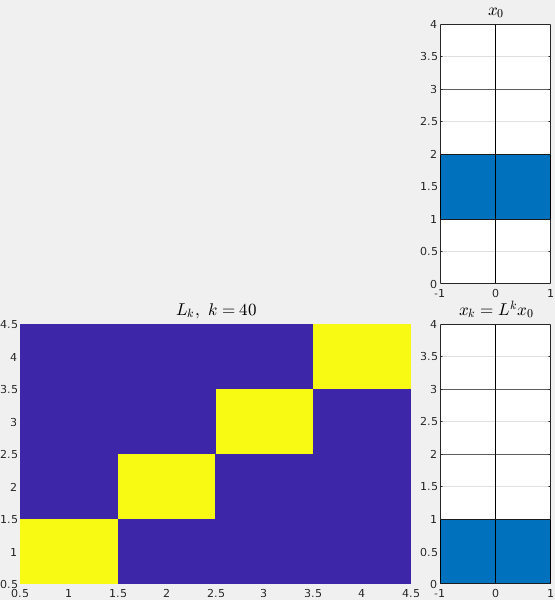

T = 40;

fig = figure(123);
fig.Position(3:4) = [555,600];
fig.Visible = 'on';

Tl = tiledlayout(2,4,"TileSpacing","tight","Padding","tight","TileIndexing","rowmajor");

ax1 = nexttile(4); hold on, grid on, box on
Br0 = barh(0.5:n,L*[x0 -x0],1,'stacked');
Br0(2).FaceColor = Br0(1).FaceColor;
yline(0:n);
ylim([0,n])
title('$x_0$','Interpreter','latex','FontSize',12)

ax2 = nexttile(5,[1,3]); hold on, grid on, box on;
Img = imagesc(L);
Tl = title("$L_k,~ \makebox[2cm]{$k = 1\hfill$}$",'Interpreter','latex','FontSize',12);

ax3 = nexttile(8); hold on, grid on, box on;
Brn = barh(0.5:n,[x0 -x0],1,'stacked');
Brn(2).FaceColor = Brn(1).FaceColor;
yline(0:n);
ylim([0,n])
title('$x_k = L^k x_0$','Interpreter','latex','FontSize',12)

Ak = eye(n);
for k = 1:T
    Ak = Ak*L;
    xk = Ak*x0;
    se_hatv = eig(Ak);

    Brn(1).YData = xk;
    Brn(2).YData = -xk;
    
    Img.CData = Ak;

    Tl.String = "$L_k,~ k = " + num2str(k) + "$";
    drawnow
end